% Number of elements to divide the blade into
N_elements = 30;

rotor_start_radius = 0.12;
rotor_radius = 0.5;
number_blades = 3;
tip_speed_ratio = 3;
angle_of_attack = deg2rad(10);

chord_root = 0.2;
chord_tip = 0.1;
chord_distribution = linspace(chord_root, chord_tip, N_elements);

% Radius of each element form axis of rotation
blade_r = linspace(rotor_start_radius, rotor_radius, N_elements);

load('S822_CL_Lookup.mat')
load('S822_Re_Values.mat')
load('S822_Alpha_Values.mat')

C_L_lookup = struct("C_L", S822_CL_Lookup, "angle_of_attack", S822_Alpha_Values, "reynolds", S822_Re_Values);

% Set conditions for convergence
max_iterations = 10000;
relaxation_factor = 0.2;
ratio_closeness = 0.01;  % Ratio (n + 1) / n must be within ratio_closeness to 1

% Table to hold data at each rotor element
data_variables = ["inflow_angle", "axial_induction_factor", "angular_induction_factor", "pitch_angle"];
data = table('Size', [N_elements, length(data_variables)], 'VariableTypes', repmat({'double'}, 1, length(data_variables)), 'VariableNames', data_variables);

% Initialise induction factors with sensible starting points
data.axial_induction_factor = ones(N_elements, 1) .* 1/3;
data.angular_induction_factor = zeros(N_elements, 1);

% Initialise variation table to have same format as data table
variation = data;

out = [];
iteration = 1;
ratio = 0;

while ~(all(ratio + ratio_closeness > 1) && all(ratio - ratio_closeness < 1)) && iteration < max_iterations
    % Save historical data to visualise convergence
    for j = 1:length(data_variables)
        out(iteration, :, j) = data.(data_variables(j))(:);
    end
    
    % Calculate new values
    data_new = iter_solver(data, tip_speed_ratio, blade_r, angle_of_attack, chord_distribution, number_blades, C_L_lookup);
    
    ratio = ones(length(data_variables), 1);
    
    % Calculate ratio, update data considering relaxation factor
    for j = 1:length(data_variables)
        % Calculate ratio
        temp_ratio = data_new.(data_variables(j)) ./ data.(data_variables(j));
        
        % Centre around 0
        temp_ratio = temp_ratio - 1;
        
        % Find maximum absolute value (worst case ratio)
        ratio(j) = max(abs(temp_ratio)) + 1;
        
        variation.(data_variables(j)) = data_new.(data_variables(j)) - data.(data_variables(j));
        data.(data_variables(j)) = data.(data_variables(j)) + variation.(data_variables(j)) .* relaxation_factor;
    end
    
    iteration = iteration + 1;
end

fprintf("Number of iterations: %d", iteration)

Number of iterations: 40

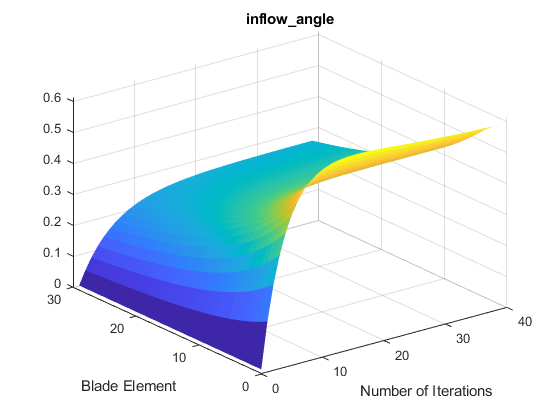

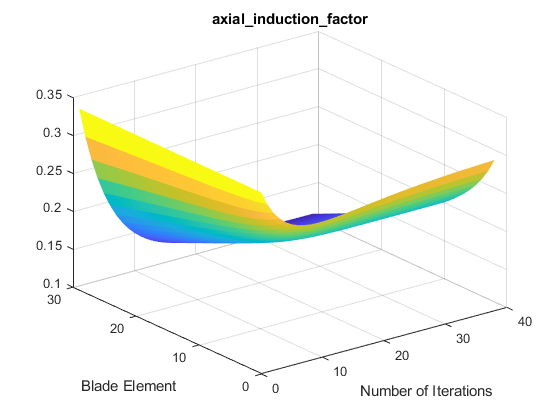

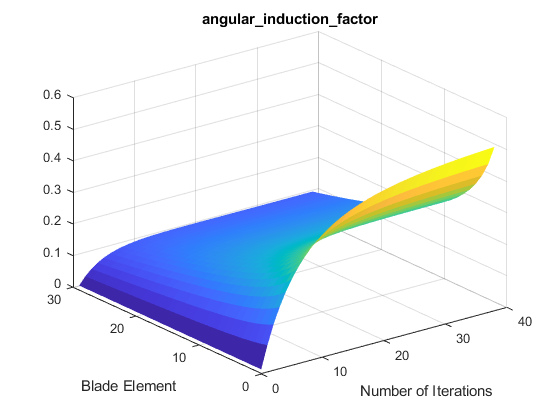

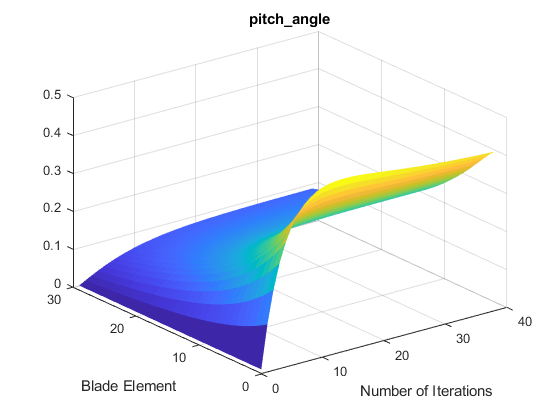


% Plot all convergences
for i = 1:length(data_variables)
    figure(i)
    s = surf(out(:, :, i)');
    s.EdgeColor = 'none';
    title(data_variables(i), 'Interpreter', 'none')
    xlabel("Number of Iterations");
    ylabel("Blade Element");
end